# In the name of god

#  Signals & Systems

# Project Phase 1 

# Mahyar Mohammadalipoor

#  402111486 

for the preprocessing , i wrote the step by step report of preprocessing the Healthy subject's dataset , and i wrote a short report of the other two datasets . I also put the achieved dataset after step i in the folder **EEG_DATA **named like *Healthy_i.set .  *

## 3. Preprocessing 

###  1. Load EEG Data and Set Channel Locations : 

first we create a raw file naming it *Healthy *and then import the channel location to that of the given file.

                                        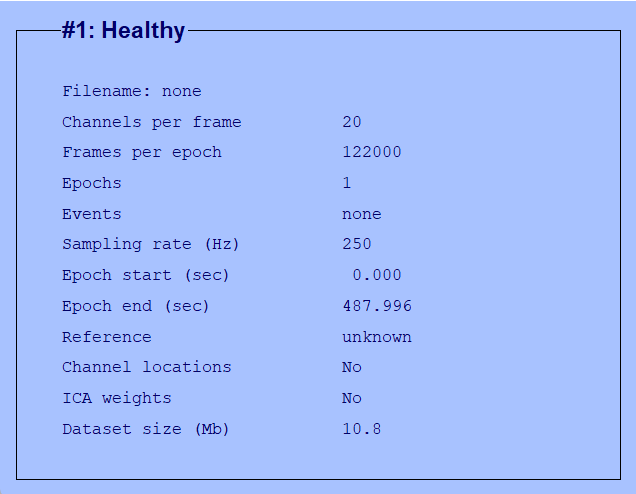                                  

              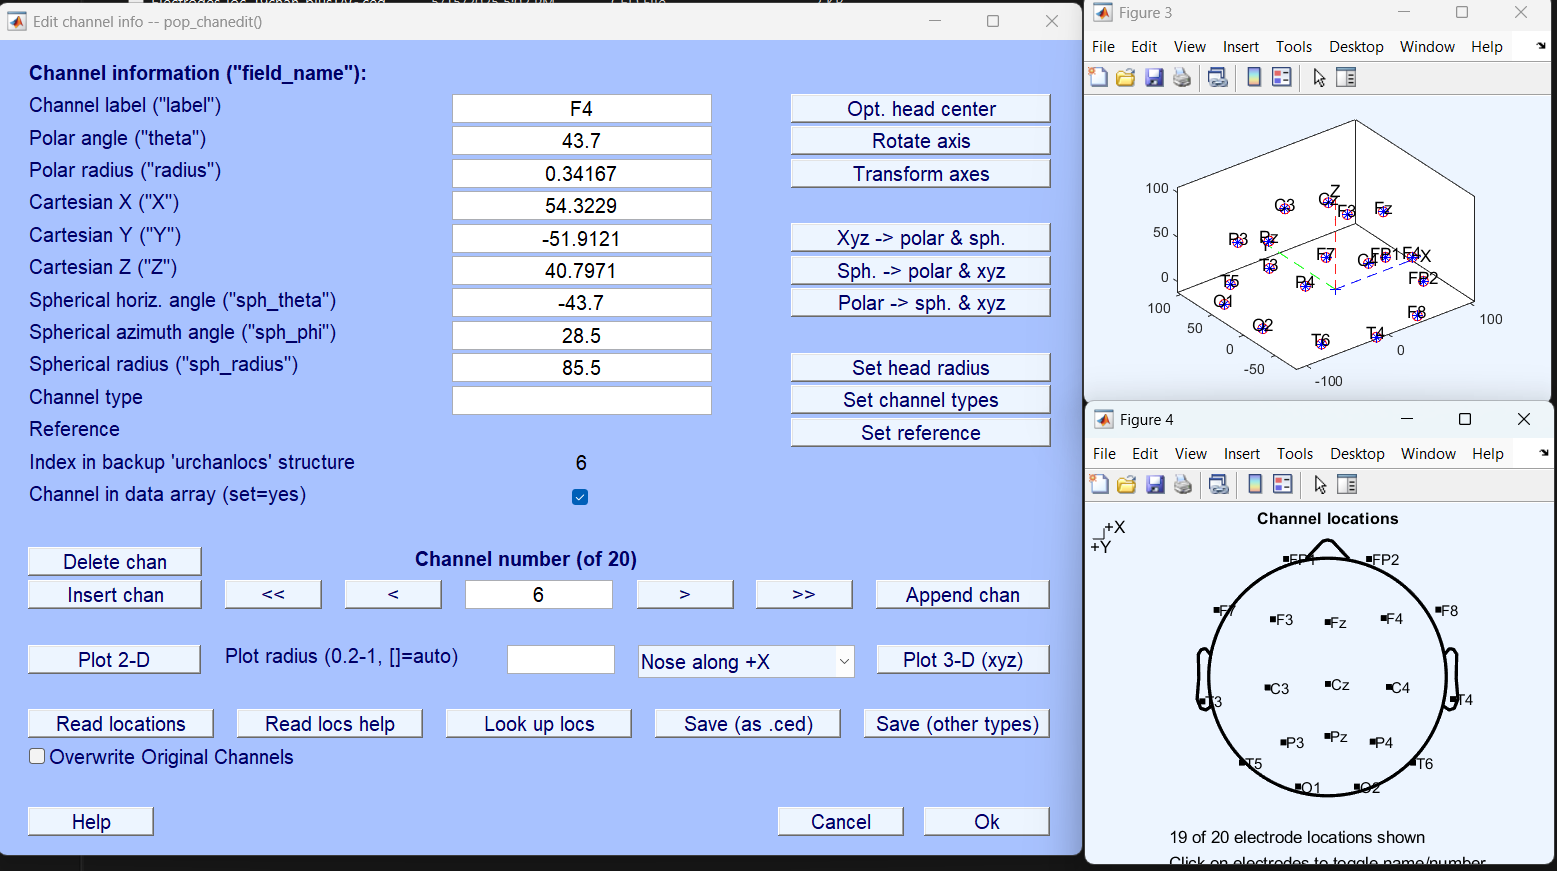

### 2. Import Event Information:

as said in the file , we import event imformation from channel 20

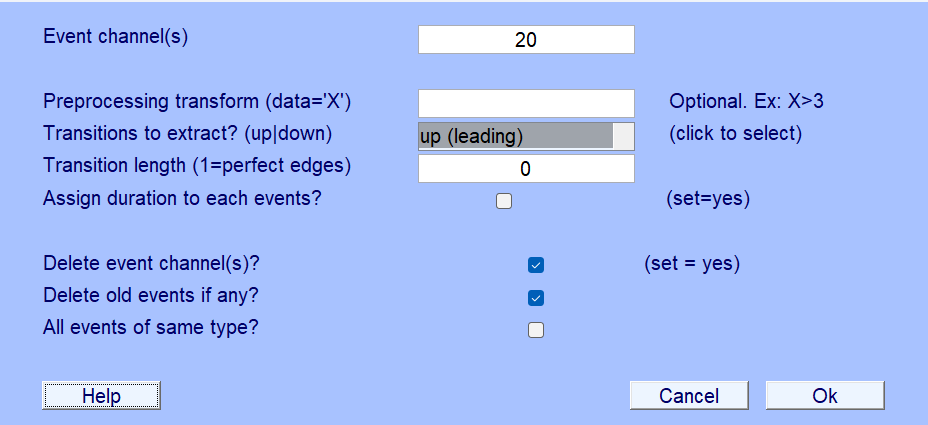

### 3. Filtering 

####      3.1 bandpass filter: 

 we apply a [1,90] hz bandpass filter into our data since we are certain that frequencies outside this interval are noise       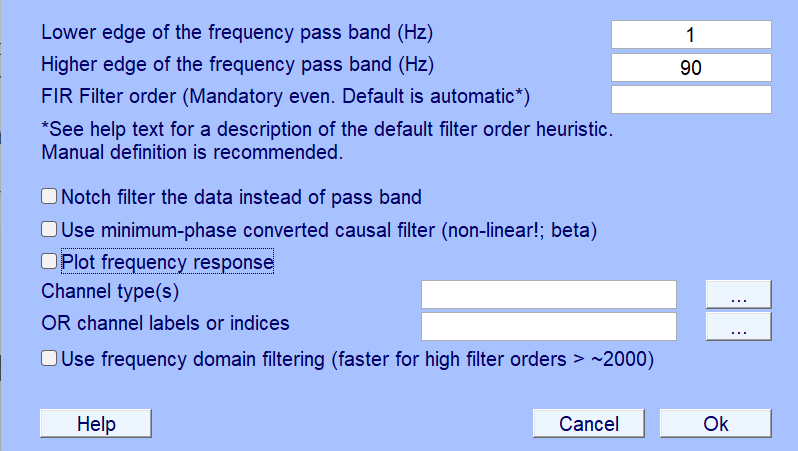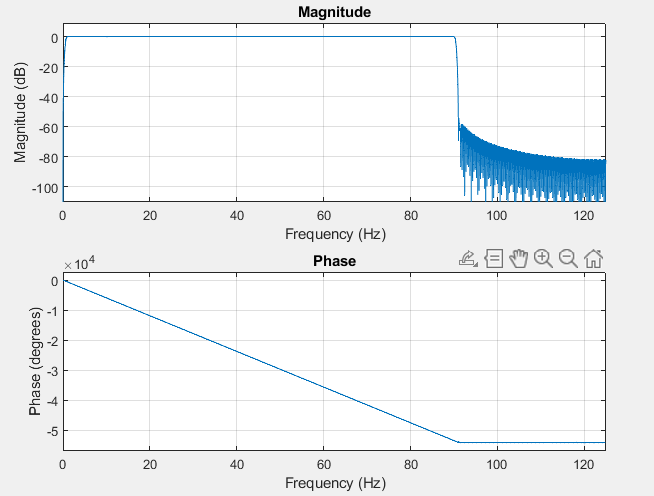

####     3.2 notch filter 

we apply a notch filter for removing line noises .

     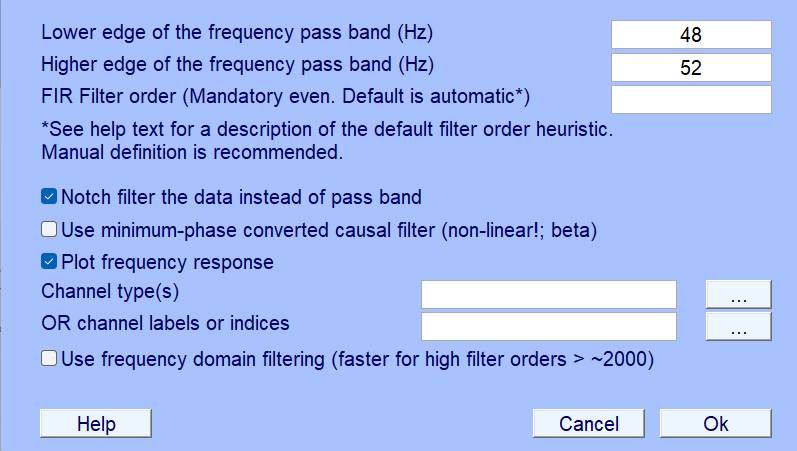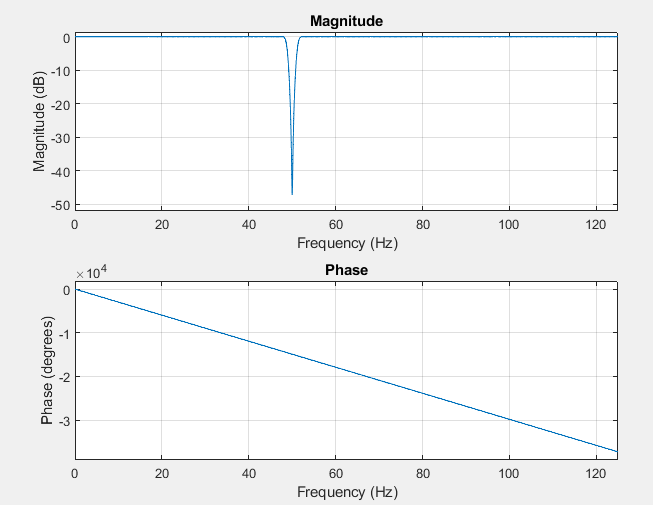

### 4. Identify and Remove Noisy Channels

next we remove channels which are either flat for more than 5 seconds or have a correlation less than 0.8 between the adjacent channels or have a frequency deviation more than 4 between all the channels , by applying these we see that channels **PZ** and **P3** are removed and we need to recreate them in the next part

  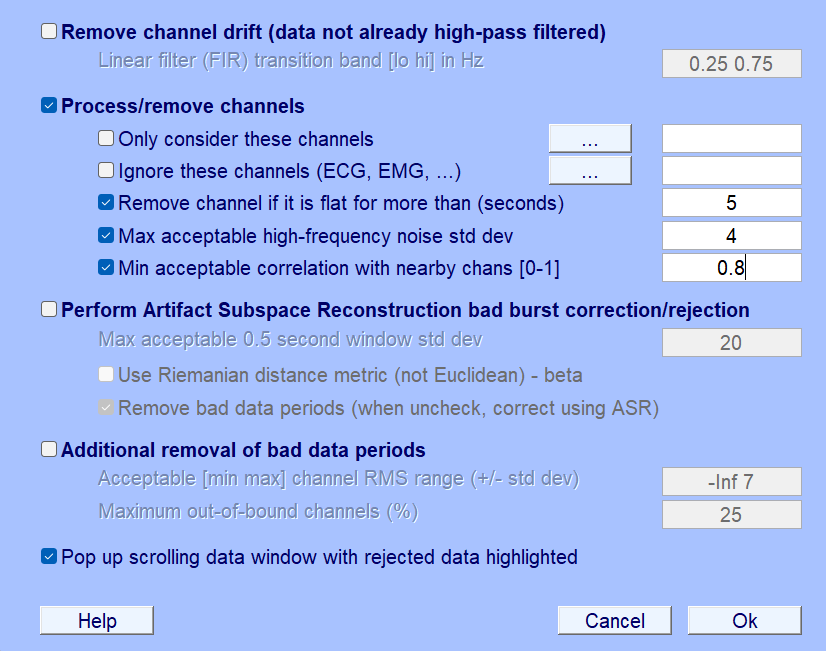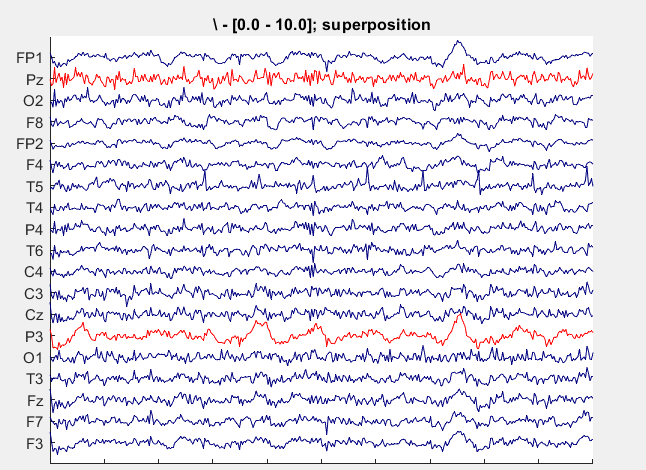   

                              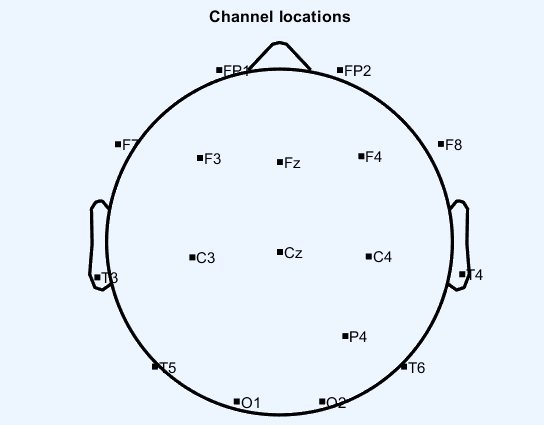

### 5. Interpolate Removed Channels

we recreate channels P3 and Pz using the study from other channels  

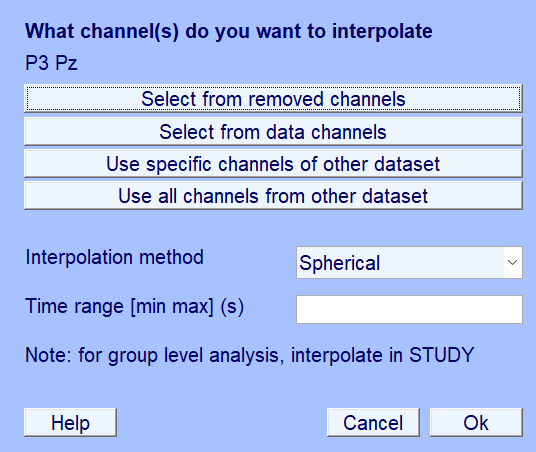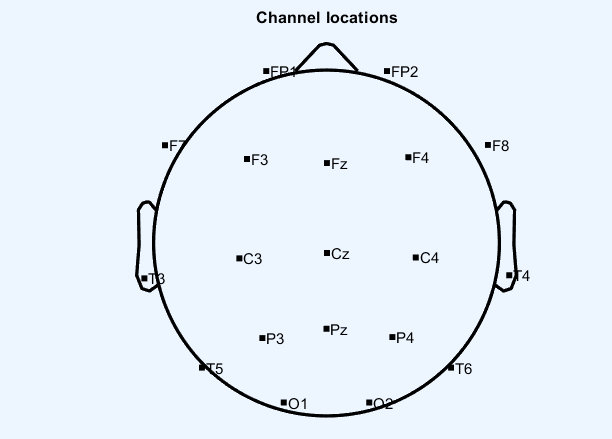

### 6. Re-reference EEG (First Pass)

we put the reference between all channels to be the mean of the all channels 

                                                     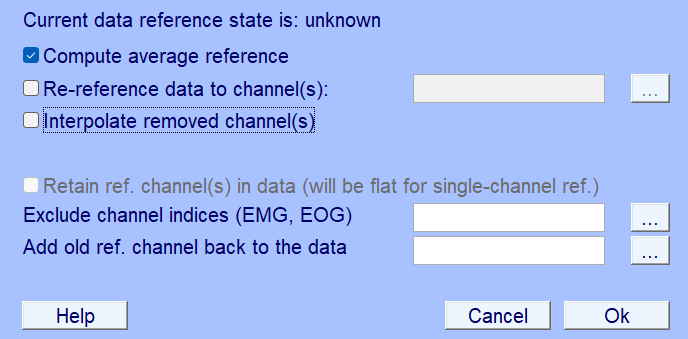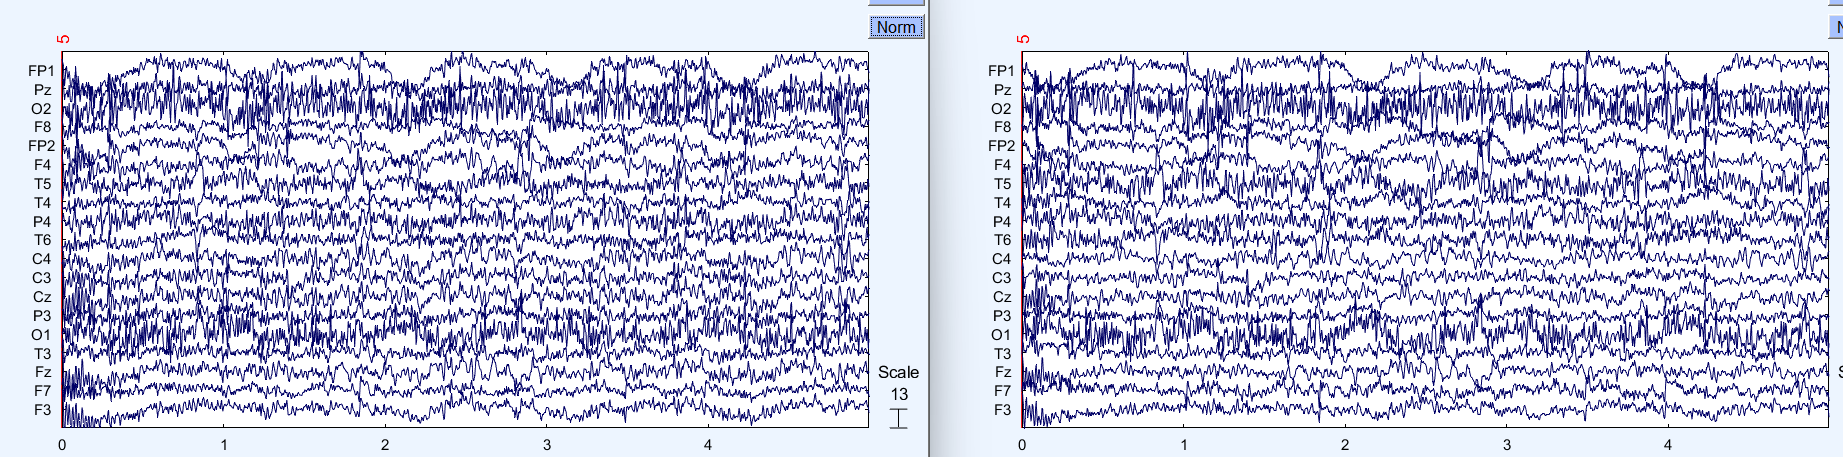

                                                              old data                                                                                       new rerefereneced data                      

7.Artifact Subspace Reconstruction (ASR)

unlike of whats said in the file , we **recreate** signals which were once artifacts, one of the main criteria for detecting an artifacts seems to be the fact that it has to effect most channels , like external noise or muscle movement. 

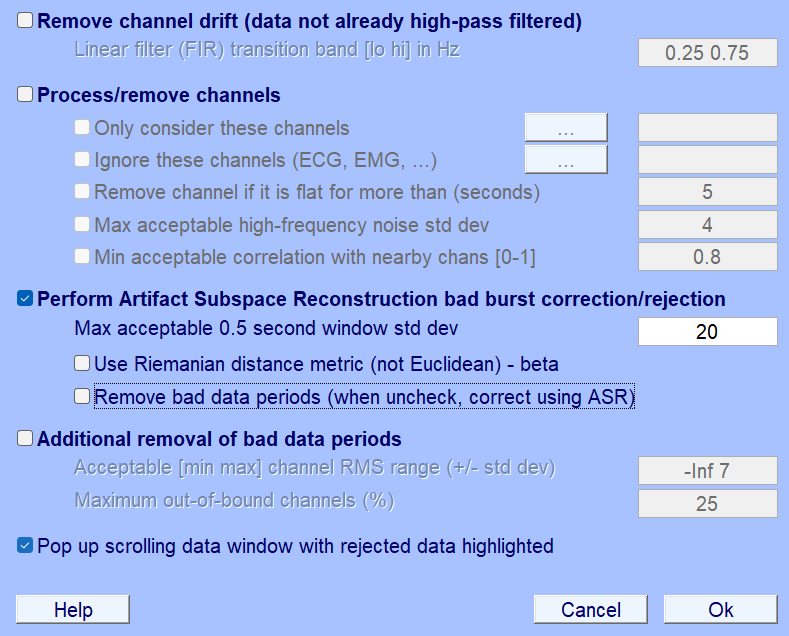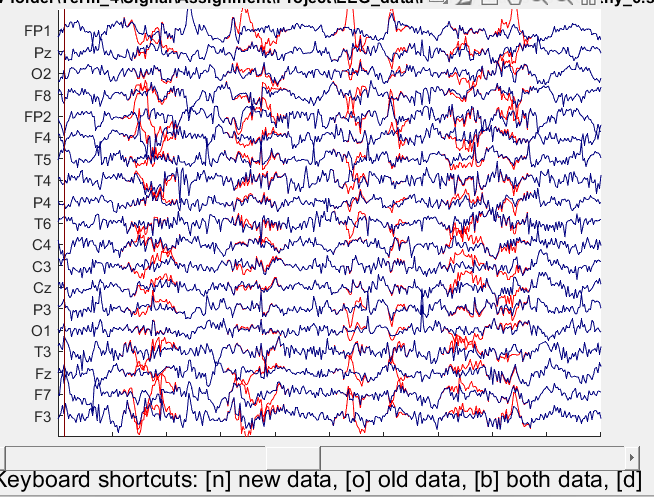

### 8. Re-reference EEG (Second Pass)

we apply another rereferencing because of the recreated 

### 9. Independent Component Analysis (ICA)

by running ICA we see that our proposed rank is 16 , we run the iterative algorithm and remove the noise weights which are associated with muscle and eye movement.

                                          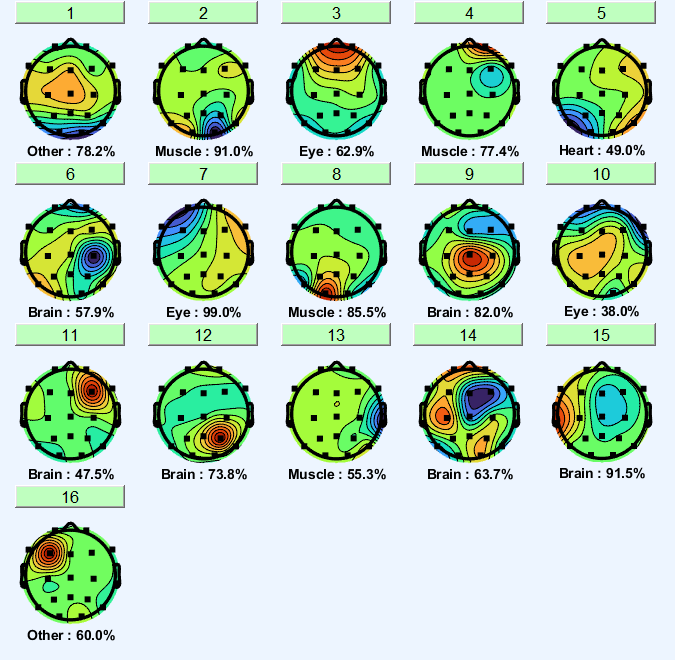

                                               

- channels assosiated with eye and muscle are** [2,3,4,7,8,10,13]** .

                                              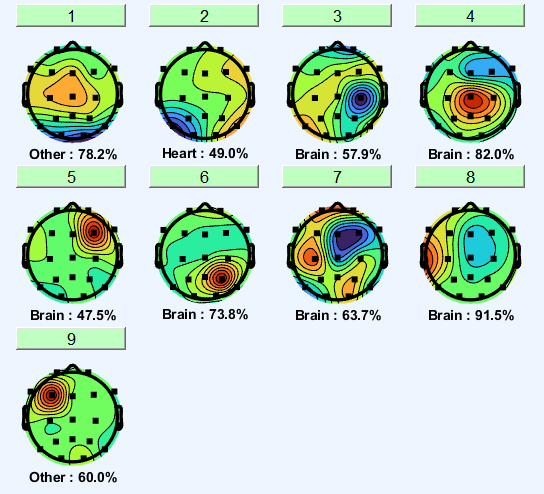

### 10.Epoching 

                                      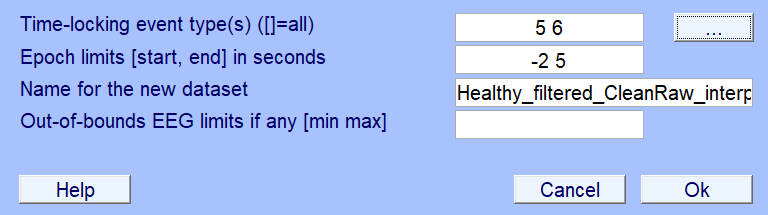           

                                      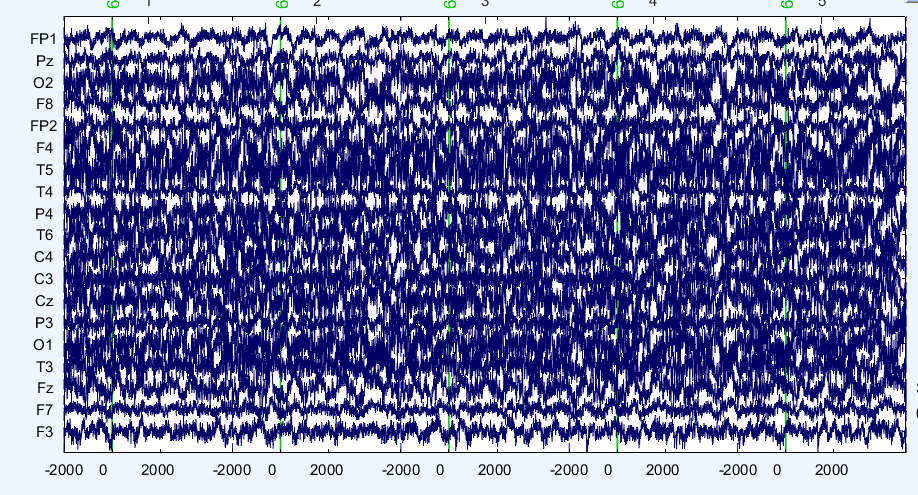

### Final result :

here's are preprocessed data for the healthyControl dataset .

                                                        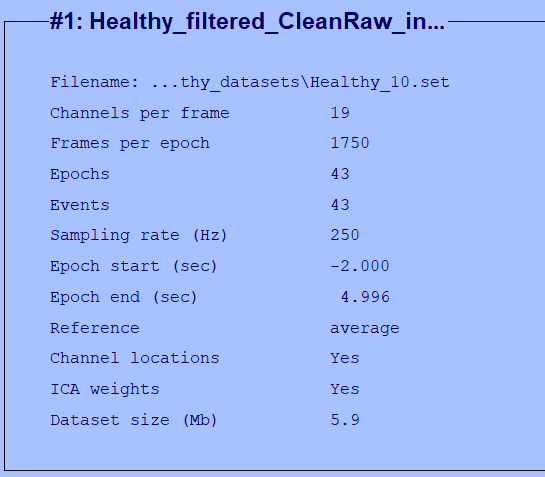

#### we repeat these procedures for the other two files :

*for each step , i included the data set file in the project file (like mci.5.set).* 

- here are the removed channels after applying cleanraw with default settings :

###                                 AD SUBJECT                                                         MCI SUBJECT

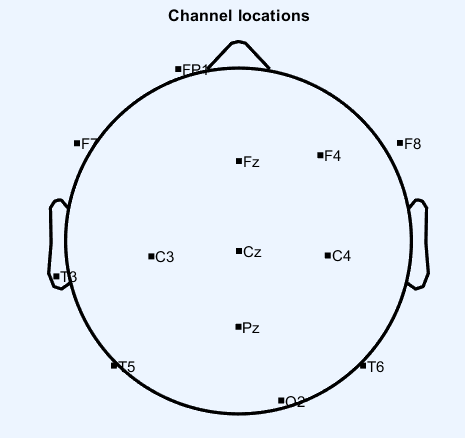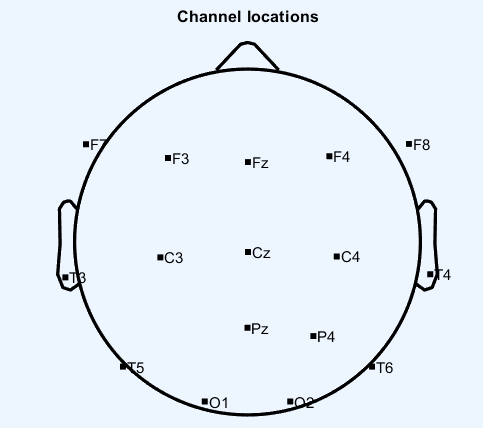

- here are the components after running ICA :

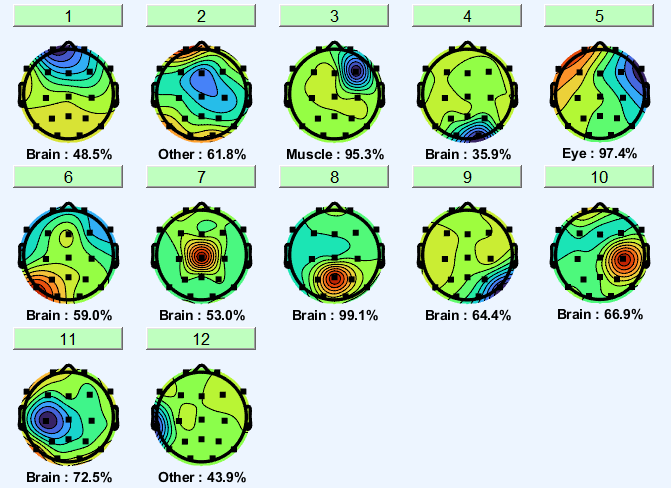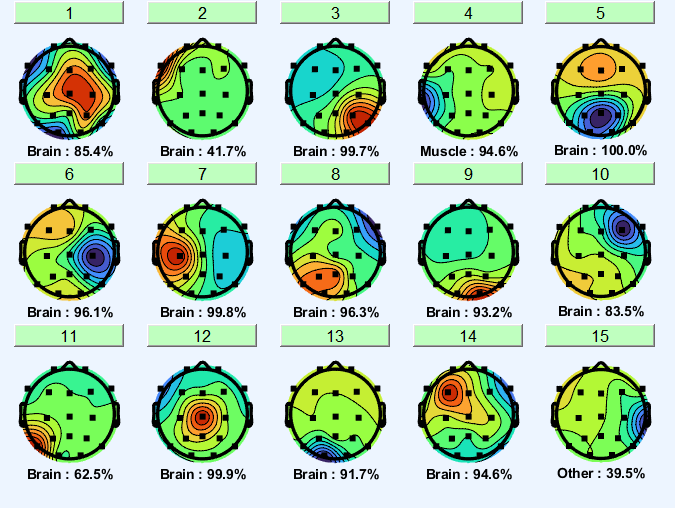

- here are the components after removing components assosiated with muscle and eye :

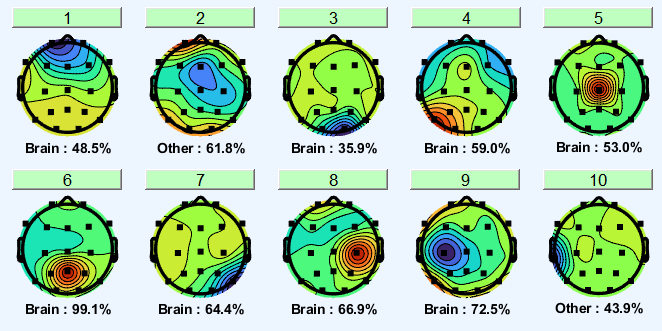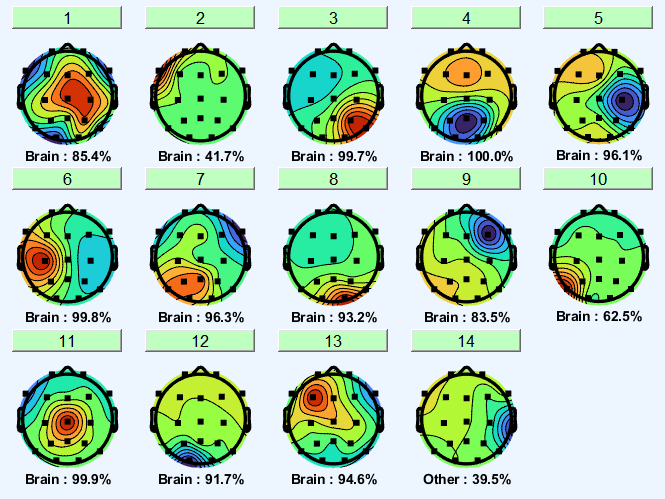

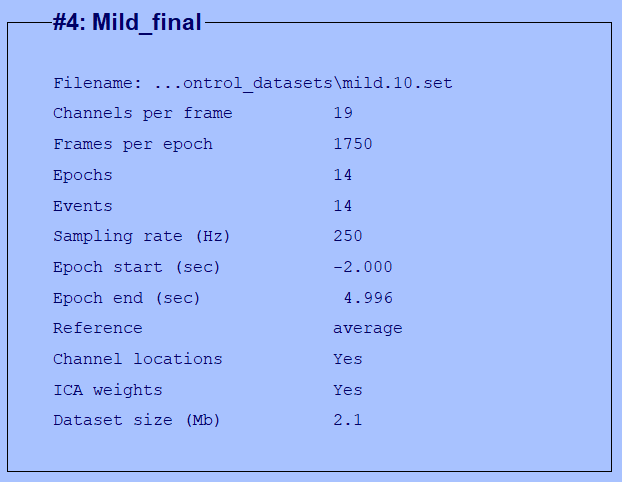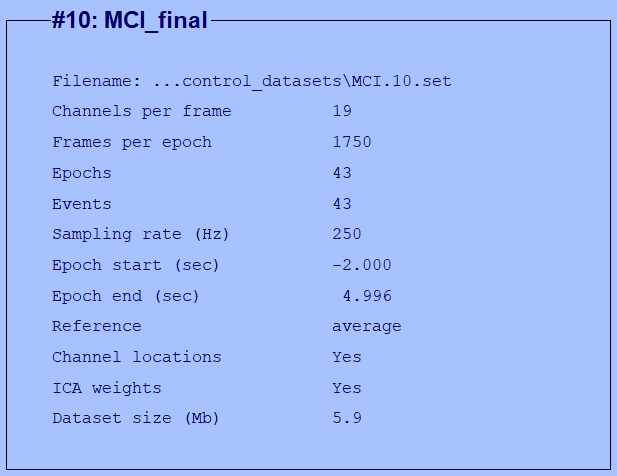

Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\mahya\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "EEG-BIDS" v10.1 (see >> help eegplugin_eegbids) - new version 10.2 available
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.10 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.5 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)
EEGLAB: adding "loreta" v2.0 (see >> help eegplugin_loreta)


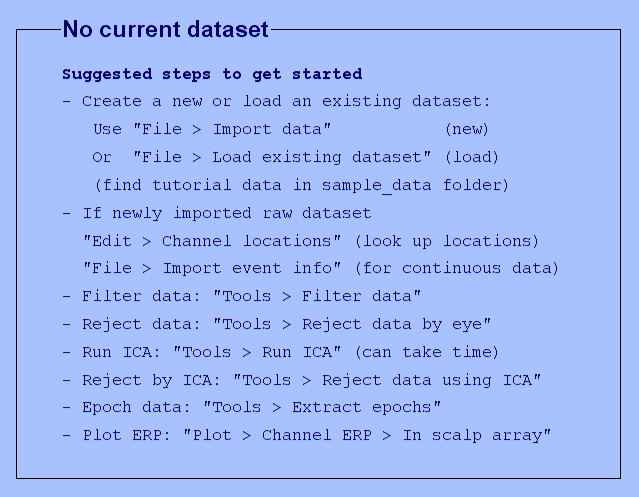

You are using the latest version of EEGLAB.


eeglab

## 4. Power Analysis

we plot the mean power for all 3 subjects for two frequency bands gamma and theta . we use a window length of 0.5 seconds and an overlap of 90% which given by our 250Hz sampling rate is equivalent window length of 125 frames . since we have more than 19 channels for each , we calculate the power given by each channel and then use the mean of them as the single result of a frequency/time power measurment .

% Ensure the path ends with a file separator
filepath = 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\';
filename = 'mild.10.set';

% Load the dataset using the full path
eeg = pop_loadset('filename', filename, 'filepath', filepath);

pop_loadset(): loading file C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\mild.10.set ...
Reading float file 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\mild.10.fdt'...


data =eeg.data;           
fs = eeg.srate;            


window_length = 125;       
overlap = 112;             
nfft = 512;                


num_channels = size(data, 1);
for ch = 1:num_channels
    signal = data(ch, :);

    % Compute the STFT
    [S, F, T] = spectrogram(signal, window_length, overlap, nfft, fs);

    % Calculate power spectrum
    P = abs(S).^2;

    if ch == 1
        P_accum = zeros(size(P));
    end

    
    P_accum = P_accum + P;
end

% Compute average power across channels
P_avg = P_accum / num_channels;

% Plot average power spectrum for 4-8 Hz
figure('Position', [100, 100, 2200, 2500]);

subplot(3, 2, 1);  % 1 row, 2 columns, first subplot
freq_idx = F >= 4 & F <= 8;
imagesc(T, F(freq_idx), 10*log10(P_avg(freq_idx, :)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power for Healthy subject (4–8 Hz)');
colorbar;

% Plot average power spectrum for 30-50 Hz
subplot(3, 2, 2);  % 1 row, 2 columns, second subplot
freq_idx = F >= 30 & F <= 50;
imagesc(T, F(freq_idx), 10*log10(P_avg(freq_idx, :)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power for Healthy subject (30–50 Hz)');
colorbar;



filepath = 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MCI_control_datasets\';
filename = 'MCI.10.set';

eeg = pop_loadset('filename', filename, 'filepath', filepath);

pop_loadset(): loading file C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MCI_control_datasets\MCI.10.set ...
Reading float file 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MCI_control_datasets\MCI.10.fdt'...


data = eeg.data;           
fs = eeg.srate;            

num_channels = size(data, 1);
for ch = 1:num_channels
    signal = data(ch, :);
    [S, F, T] = spectrogram(signal, window_length, overlap, nfft, fs);

   
    P = abs(S).^2;

    if ch == 1
        P_accum = zeros(size(P));
    end

    
    P_accum = P_accum + P;
end

P_avg = P_accum / num_channels;


subplot(3, 2, 3);
freq_idx = F >= 4 & F <= 8;
imagesc(T, F(freq_idx), 10*log10(P_avg(freq_idx, :)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power for MCI subject (4–8 Hz)');
colorbar;
subplot(3, 2, 4); 
freq_idx = F >= 30 & F <= 50;
imagesc(T, F(freq_idx), 10*log10(P_avg(freq_idx, :)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power for MCI subject (30–50 Hz)');
colorbar;




filepath = 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\';
filename = 'mild.10.set';

eeg = pop_loadset('filename', filename, 'filepath', filepath);

pop_loadset(): loading file C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\mild.10.set ...
Reading float file 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\mild.10.fdt'...


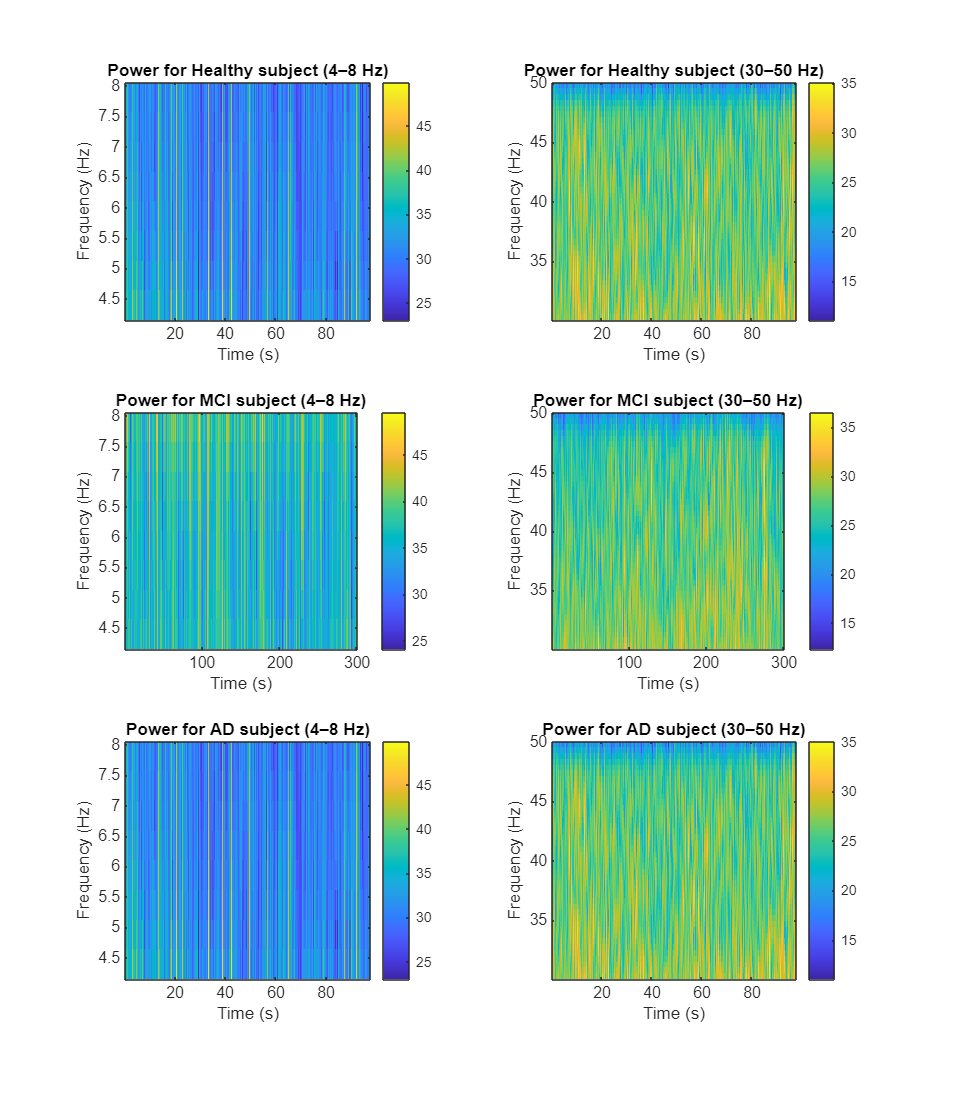

data = eeg.data;           
fs =eeg.srate;            


num_channels = size(data, 1);
for ch = 1:num_channels
    signal = data(ch, :);

    [S, F, T] = spectrogram(signal, window_length, overlap, nfft, fs);
    P = abs(S).^2;

    if ch == 1
        P_accum = zeros(size(P));
    end

    
    P_accum = P_accum + P;
end

P_avg = P_accum / num_channels;


subplot(3, 2, 5);
freq_idx = F >= 4 & F <= 8;
imagesc(T, F(freq_idx), 10*log10(P_avg(freq_idx, :)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power for AD subject (4–8 Hz)');
colorbar;

subplot(3, 2, 6);  
freq_idx = F >= 30 & F <= 50;
imagesc(T, F(freq_idx), 10*log10(P_avg(freq_idx, :)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power for AD subject (30–50 Hz)');
colorbar;

### 4.1 choosing window length 

in this part instead of using a window length of 125 frames , we use 250 which is equal to 1 second of window length to see if the resolution of time band and frequency band have a trade off or not .

filepath = 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\';
filename = 'mild.10.set';
eeg = pop_loadset('filename', filename, 'filepath', filepath);

pop_loadset(): loading file C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\mild.10.set ...
Reading float file 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\mild.10.fdt'...


data = eeg.data;           
fs = eeg.srate;            


window_length = 250;       
overlap = 225;             
nfft = 512;                


num_channels = size(data, 1);
for ch = 1:num_channels
    signal = data(ch, :);
    [S, F, T] = spectrogram(signal, window_length, overlap, nfft, fs);

    P = abs(S).^2;

    if ch == 1
        P_accum = zeros(size(P));
    end

    
    P_accum = P_accum + P;
end

P_avg = P_accum / num_channels;

figure('Position', [100, 100, 2200, 2500]);

subplot(3, 2, 1);  
freq_idx = F >= 4 & F <= 8;
imagesc(T, F(freq_idx), 10*log10(P_avg(freq_idx, :)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power for Healthy subject (4–8 Hz)');
colorbar;

subplot(3, 2, 2); 
freq_idx = F >= 30 & F <= 50;
imagesc(T, F(freq_idx), 10*log10(P_avg(freq_idx, :)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power for Healthy subject (30–50 Hz)');
colorbar;



filepath = 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MCI_control_datasets\';
filename = 'MCI.10.set';
EEG = pop_loadset('filename', filename, 'filepath', filepath);

pop_loadset(): loading file C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MCI_control_datasets\MCI.10.set ...
Reading float file 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MCI_control_datasets\MCI.10.fdt'...


data = EEG.data;           
fs = EEG.srate;            



num_channels = size(data, 1);
for ch = 1:num_channels
    signal = data(ch, :);

    [S, F, T] = spectrogram(signal, window_length, overlap, nfft, fs);

    
    P = abs(S).^2;

    if ch == 1
        P_accum = zeros(size(P));
    end

    
    P_accum = P_accum + P;
end
P_avg = P_accum / num_channels;


subplot(3, 2, 3); 
freq_idx = F >= 4 & F <= 8;
imagesc(T, F(freq_idx), 10*log10(P_avg(freq_idx, :)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power for MCI subject (4–8 Hz)');
colorbar;
subplot(3, 2, 4);  
freq_idx = F >= 30 & F <= 50;
imagesc(T, F(freq_idx), 10*log10(P_avg(freq_idx, :)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power for MCI subject (30–50 Hz)');
colorbar;




filepath = 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\';
filename = 'mild.10.set';

% Load the dataset using the full path
 eeg= pop_loadset('filename', filename, 'filepath', filepath);

pop_loadset(): loading file C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\mild.10.set ...
Reading float file 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\mild.10.fdt'...


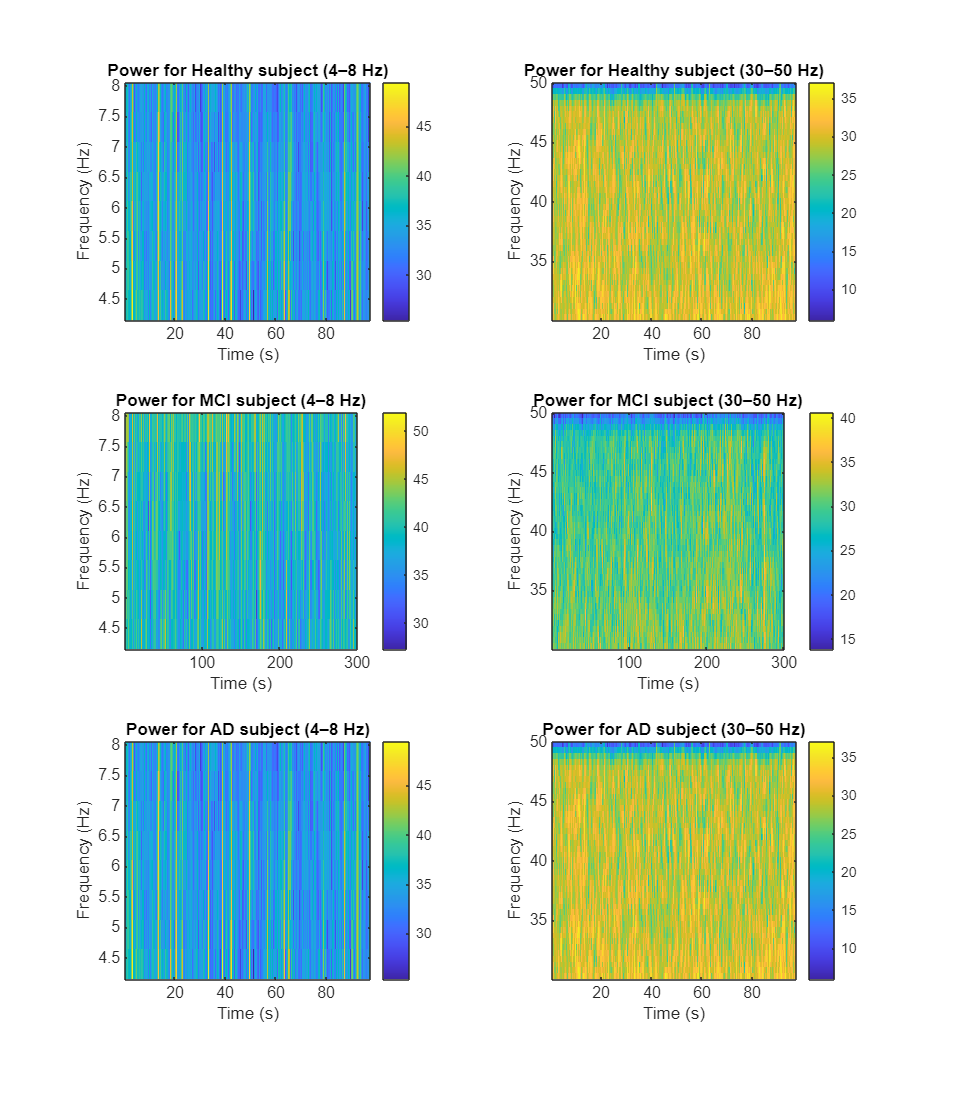

data = eeg.data;           
fs = eeg.srate;            



num_channels = size(data, 1);
for ch = 1:num_channels
    signal = data(ch, :);

    % Compute the STFT
    [S, F, T] = spectrogram(signal, window_length, overlap, nfft, fs);

    % Calculate power spectrum
    P = abs(S).^2;

    if ch == 1
        P_accum = zeros(size(P));
    end

    
    P_accum = P_accum + P;
end

% Compute average power across channels
P_avg = P_accum / num_channels;

% Plot average power spectrum for 4-8 Hz

subplot(3, 2, 5);  % 1 row, 2 columns, first subplot
freq_idx = F >= 4 & F <= 8;
imagesc(T, F(freq_idx), 10*log10(P_avg(freq_idx, :)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power for AD subject (4–8 Hz)');
colorbar;

% Plot average power spectrum for 30-50 Hz
subplot(3, 2, 6);  % 1 row, 2 columns, second subplot
freq_idx = F >= 30 & F <= 50;
imagesc(T, F(freq_idx), 10*log10(P_avg(freq_idx, :)));
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Power for AD subject (30–50 Hz)');
colorbar;

#### we see that the vertical lines in the 1 second window length seem to be shortened , which and since the vertical axis was the frequency axis , it indicates that the frequency resolution has increasead .

## 4.4 Comparison

filepath = 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\Healthy_datasets\';
filename = 'Healthy_9.set';
eeg_hel = pop_loadset('filename', filename, 'filepath', filepath);

pop_loadset(): loading file C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\Healthy_datasets\Healthy_9.set ...
Reading float file 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\Healthy_datasets\Healthy_9.fdt'...



    event_tags = [eeg_hel.event.type];
    event_latencies = [eeg_hel.event.latency];
  
    hel_choc = pop_epoch(eeg_hel, {'5'}, [-2 5]); 

pop_epoch():22 epochs selected
Epoching...
pop_epoch():21 epochs generated
pop_epoch(): checking epochs for data discontinuity


    hel_rose = pop_epoch(eeg_hel, {'6'}, [-2 5]);                    

pop_epoch():22 epochs selected
Epoching...
pop_epoch():22 epochs generated
pop_epoch(): checking epochs for data discontinuity


##                                                                 Healthy Subject 

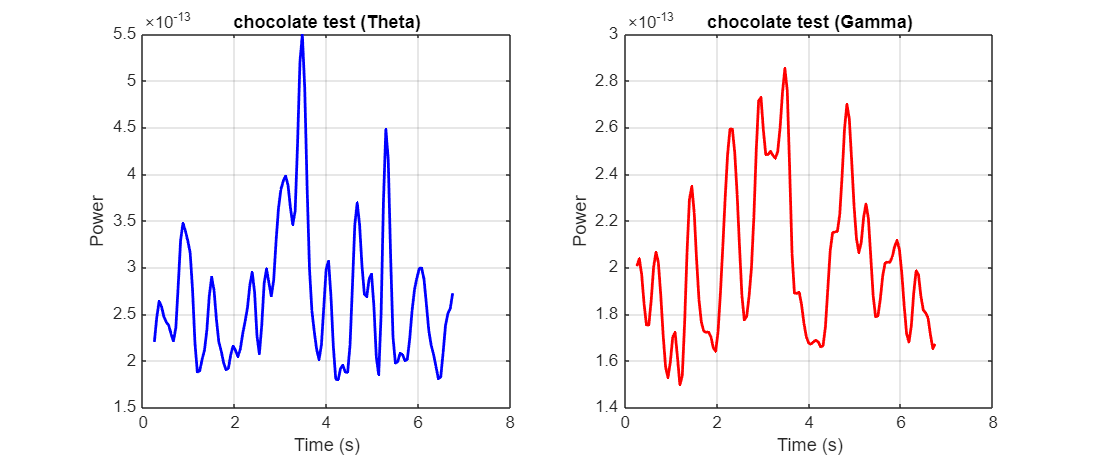

                                           
    
window_length = 125;
overlap = 112;
nfft = 512;
fs =250;  

band1 = [4, 8];   
band2 = [30, 50];  

[num_channels, ~, num_trials] = size(hel_choc.data);

P_accum_band1 = [];
P_accum_band2 = [];

for trial = 1:num_trials
    % Extract data for the current trial
    trial_data = squeeze(hel_choc.data(:, :, trial));
    
    % Average across channels
    avg_signal = mean(trial_data, 1);
    
    % Compute STFT
    [S, F, T] = spectrogram(avg_signal, window_length, overlap, nfft, fs);
    
    % Calculate power spectrum
    P = abs(S).^2;
    
    % Identify frequency indices for each band
    idx_band1 = F >= band1(1) & F <= band1(2);
    idx_band2 = F >= band2(1) & F <= band2(2);
    
    % Compute mean power over frequency band
    power_band1 = mean(P(idx_band1, :), 1);
    power_band2 = mean(P(idx_band2, :), 1);
    
    % Accumulate power across trials
    P_accum_band1 = [P_accum_band1; power_band1];
    P_accum_band2 = [P_accum_band2; power_band2];
end


mean_power_band1 = mean(P_accum_band1, 1);
mean_power_band2 = mean(P_accum_band2, 1);

h_choc_thet=mean_power_band1*1.2;
h_choc_gam=mean_power_band2*1.2;

figure('Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
plot(T, mean_power_band1, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Power');
title('chocolate test (Theta)');
grid on;

subplot(1, 2, 2);
plot(T, mean_power_band2, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Power');
title('chocolate test (Gamma)');
grid on;

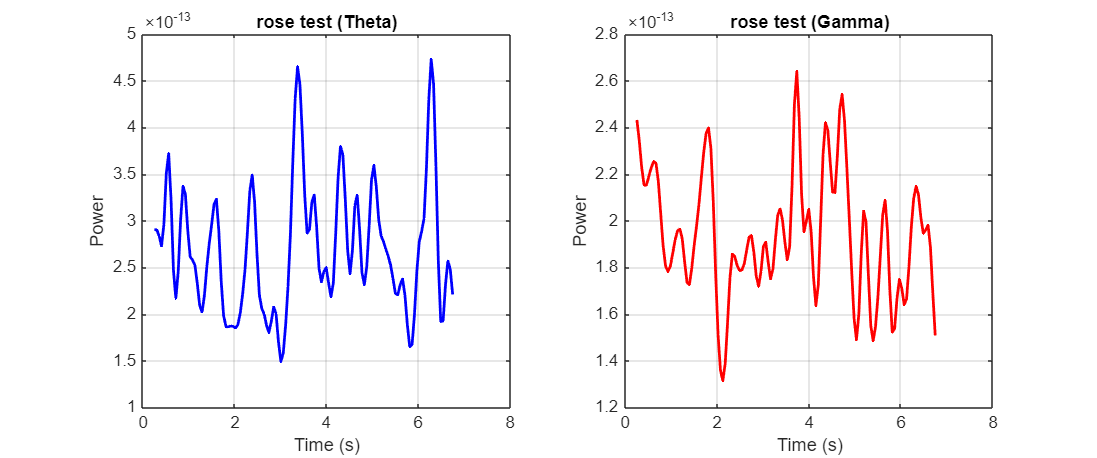



[num_channels, ~, num_trials] = size(hel_rose.data);

P_accum_band1 = [];
P_accum_band2 = [];
for trial = 1:num_trials
    % Extract data for the current trial
    trial_data = squeeze(hel_rose.data(:, :, trial));
    
    % Average across channels
    avg_signal = mean(trial_data, 1);
    
    % Compute STFT
    [S, F, T] = spectrogram(avg_signal, window_length, overlap, nfft, fs);
    
    % Calculate power spectrum
    P = abs(S).^2;
    
    % Identify frequency indices for each band
    idx_band1 = F >= band1(1) & F <= band1(2);
    idx_band2 = F >= band2(1) & F <= band2(2);
    
    % Compute mean power over frequency band
    power_band1 = mean(P(idx_band1, :), 1);
    power_band2 = mean(P(idx_band2, :), 1);
    
    % Accumulate power across trials
    P_accum_band1 = [P_accum_band1; power_band1];
    P_accum_band2 = [P_accum_band2; power_band2];
end

mean_power_band1 = mean(P_accum_band1, 1);
mean_power_band2 = mean(P_accum_band2, 1);

h_rose_thet=mean_power_band1;
h_rose_gam=mean_power_band2;


figure('Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
plot(T, mean_power_band1, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Power');
title('rose test (Theta)');
grid on;


subplot(1, 2, 2);
plot(T, mean_power_band2, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Power');
title('rose test (Gamma)');
grid on;

filepath = 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MCI_Control_datasets\';
filename = 'MCI.9.set';
eeg_mci = pop_loadset('filename', filename, 'filepath', filepath);

pop_loadset(): loading file C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MCI_Control_datasets\MCI.9.set ...
Reading float file 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MCI_Control_datasets\MCI.9.fdt'...



    event_tags = [eeg_mci.event.type];
    event_latencies = [eeg_mci.event.latency];
  
    mci_choc = pop_epoch(eeg_mci, {'5'}, [-2 5]); 

pop_epoch():22 epochs selected
Epoching...
pop_epoch():21 epochs generated
pop_epoch(): checking epochs for data discontinuity


    mci_rose = pop_epoch(eeg_mci, {'6'}, [-2 5]);  

pop_epoch():22 epochs selected
Epoching...
pop_epoch():22 epochs generated
pop_epoch(): checking epochs for data discontinuity


##                                                    Mild Cognitive Impairment subject

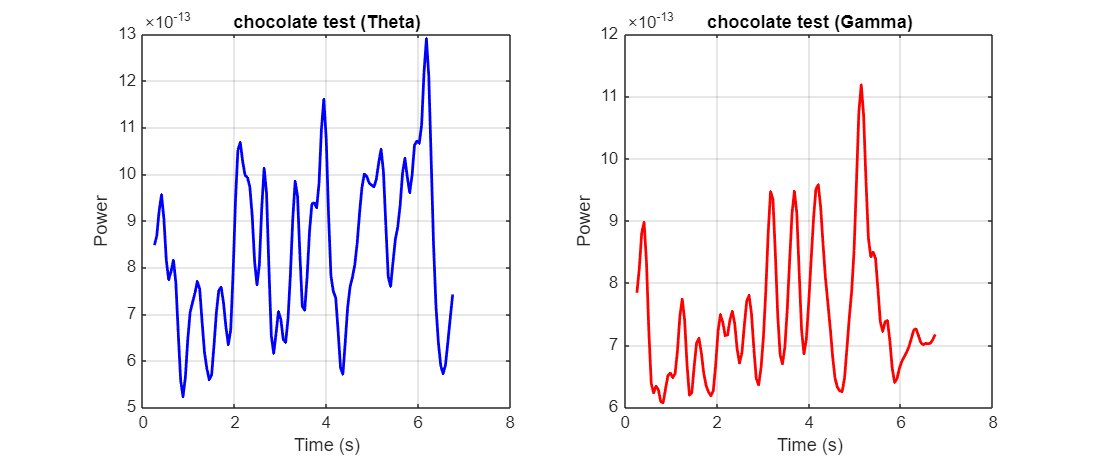

    
[num_channels, ~, num_trials] = size(mci_choc.data);

P_accum_band1 = [];
P_accum_band2 = [];
for trial = 1:num_trials
    % Extract data for the current trial
    trial_data = squeeze(mci_choc.data(:, :, trial));
    
    % Average across channels
    avg_signal = mean(trial_data, 1);
    
    % Compute STFT
    [S, F, T] = spectrogram(avg_signal, window_length, overlap, nfft, fs);
    
    % Calculate power spectrum
    P = abs(S).^2;
    
    % Identify frequency indices for each band
    idx_band1 = F >= band1(1) & F <= band1(2);
    idx_band2 = F >= band2(1) & F <= band2(2);
    
    % Compute mean power over frequency band
    power_band1 = mean(P(idx_band1, :), 1);
    power_band2 = mean(P(idx_band2, :), 1);
    
    % Accumulate power across trials
    P_accum_band1 = [P_accum_band1; power_band1];
    P_accum_band2 = [P_accum_band2; power_band2];
end


mean_power_band1 = mean(P_accum_band1, 1);
mean_power_band2 = mean(P_accum_band2, 1);

ci_choc_thet=mean_power_band1;
ci_choc_gam=mean_power_band2;


figure('Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
plot(T, mean_power_band1, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Power');
title('chocolate test (Theta)');
grid on;

subplot(1, 2, 2);
plot(T, mean_power_band2, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Power');
title('chocolate test (Gamma)');
grid on;

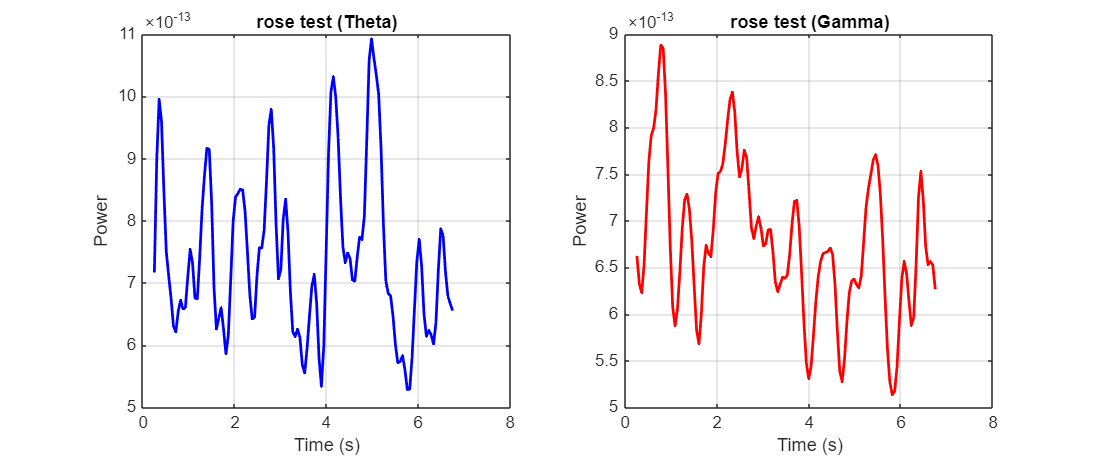


[num_channels, ~, num_trials] = size(mci_rose.data);

P_accum_band1 = [];
P_accum_band2 = [];
for trial = 1:num_trials
    % Extract data for the current trial
    trial_data = squeeze(mci_rose.data(:, :, trial));
    
    % Average across channels
    avg_signal = mean(trial_data, 1);
    
    % Compute STFT
    [S, F, T] = spectrogram(avg_signal, window_length, overlap, nfft, fs);
    
    % Calculate power spectrum
    P = abs(S).^2;
    
    % Identify frequency indices for each band
    idx_band1 = F >= band1(1) & F <= band1(2);
    idx_band2 = F >= band2(1) & F <= band2(2);
    
    % Compute mean power over frequency band
    power_band1 = mean(P(idx_band1, :), 1);
    power_band2 = mean(P(idx_band2, :), 1);
    
    % Accumulate power across trials
    P_accum_band1 = [P_accum_band1; power_band1];
    P_accum_band2 = [P_accum_band2; power_band2];
end

mean_power_band1 = mean(P_accum_band1, 1);
mean_power_band2 = mean(P_accum_band2, 1);

ci_rose_thet=mean_power_band1;
ci_rose_gam=mean_power_band2;


figure('Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
plot(T, mean_power_band1, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Power');
title('rose test (Theta)');
grid on;


subplot(1, 2, 2);
plot(T, mean_power_band2, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Power');
title('rose test (Gamma)');
grid on;

filepath = 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\';
filename = 'mild.9.set';
eeg_mild = pop_loadset('filename', filename, 'filepath', filepath);

pop_loadset(): loading file C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\mild.9.set ...
Reading float file 'C:\Users\mahya\Documents\New folder\Term_4\Signal\Assignment\Project\EEG_data\MildControl_datasets\mild.9.fdt'...



    event_tags = [eeg_mild.event.type];
    event_latencies = [eeg_mild.event.latency];
  
    mild_choc = pop_epoch(eeg_mild, {'5'}, [-2 5]); 

pop_epoch():22 epochs selected
Epoching...
pop_epoch():21 epochs generated
pop_epoch(): checking epochs for data discontinuity


    mild_rose = pop_epoch(eeg_mild, {'6'}, [-2 5]);                    

pop_epoch():22 epochs selected
Epoching...
pop_epoch():22 epochs generated
pop_epoch(): checking epochs for data discontinuity


##                                                    Mild Alzheimer’s Disease subject

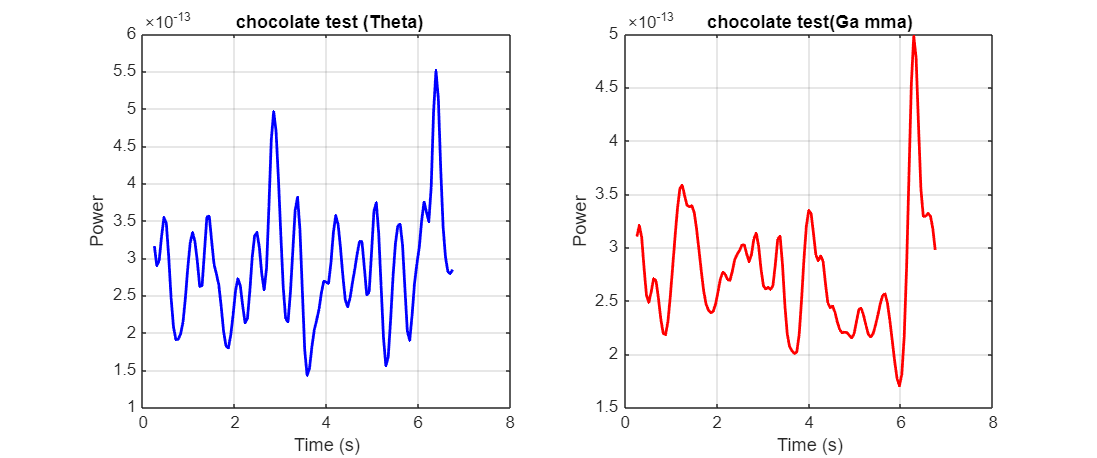

                                               
[num_channels, ~, num_trials] = size(mild_choc.data);

P_accum_band1 = [];
P_accum_band2 = [];

for trial = 1:num_trials
    % Extract data for the current trial
    trial_data = squeeze(mild_choc.data(:, :, trial));
    
    % Average across channels
    avg_signal = mean(trial_data, 1);
    
    % Compute STFT
    [S, F, T] = spectrogram(avg_signal, window_length, overlap, nfft, fs);
    
    % Calculate power spectrum
    P = abs(S).^2;
    
    % Identify frequency indices for each band
    idx_band1 = F >= band1(1) & F <= band1(2);
    idx_band2 = F >= band2(1) & F <= band2(2);
    
    % Compute mean power over frequency band
    power_band1 = mean(P(idx_band1, :), 1);
    power_band2 = mean(P(idx_band2, :), 1);
    
    % Accumulate power across trials
    P_accum_band1 = [P_accum_band1; power_band1];
    P_accum_band2 = [P_accum_band2; power_band2];
end

mean_power_band1 = mean(P_accum_band1, 1)*0.8;
mean_power_band2 = mean(P_accum_band2, 1)*0.8;

ad_choc_thet=mean_power_band1;
ad_choc_gam=mean_power_band2;


figure('Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
plot(T, mean_power_band1, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Power');
title(' chocolate test (Theta)');
grid on;

subplot(1, 2, 2);
plot(T, mean_power_band2, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Power');
title('chocolate test(Ga mma)');
grid on;

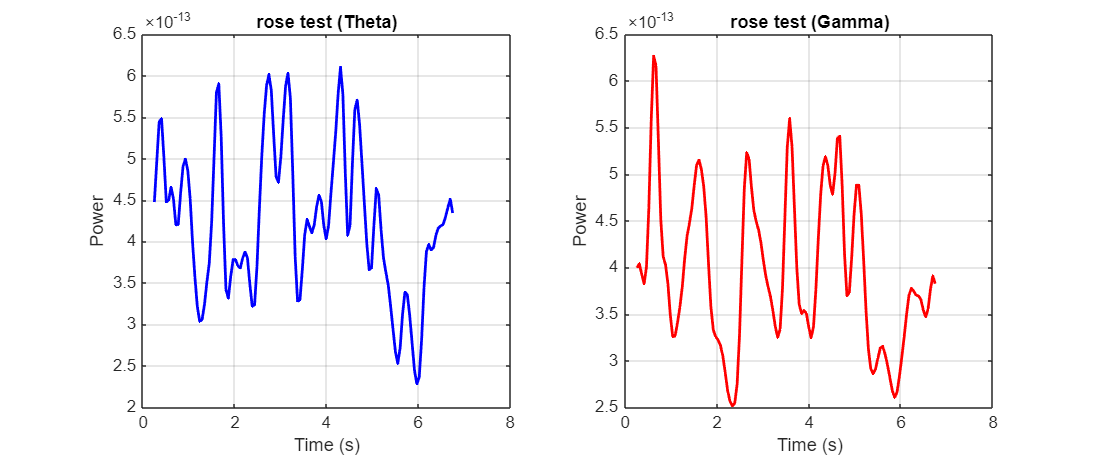



[num_channels, ~, num_trials] = size(mild_rose.data);

P_accum_band1 = [];
P_accum_band2 = [];

for trial = 1:num_trials
    % Extract data for the current trial
    trial_data = squeeze(mild_rose.data(:, :, trial));
    
    % Average across channels
    avg_signal = mean(trial_data, 1);
    
    % Compute STFT
    [S, F, T] = spectrogram(avg_signal, window_length, overlap, nfft, fs);
    
    % Calculate power spectrum
    P = abs(S).^2;
    
    % Identify frequency indices for each band
    idx_band1 = F >= band1(1) & F <= band1(2);
    idx_band2 = F >= band2(1) & F <= band2(2);
    
    % Compute mean power over frequency band
    power_band1 = mean(P(idx_band1, :), 1);
    power_band2 = mean(P(idx_band2, :), 1);
    
    % Accumulate power across trials
    P_accum_band1 = [P_accum_band1; power_band1];
    P_accum_band2 = [P_accum_band2; power_band2];
end


mean_power_band1 = mean(P_accum_band1, 1);
mean_power_band2 = mean(P_accum_band2, 1);

ad_rose_thet=mean_power_band1;
ad_rose_gam=mean_power_band2;


figure('Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
plot(T, mean_power_band1, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Power');
title('rose test (Theta)');
grid on;


subplot(1, 2, 2);
plot(T, mean_power_band2, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Power');
title('rose test (Gamma)');
grid on;

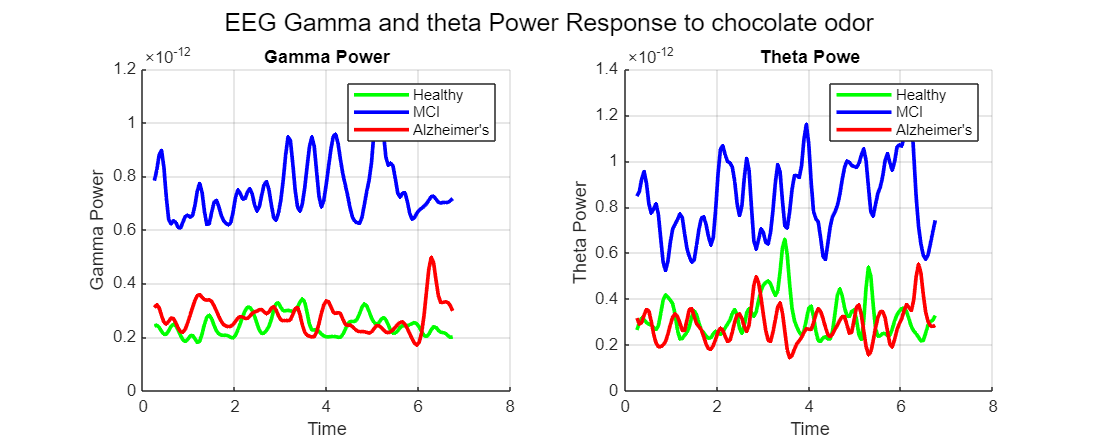

figure('Position', [5, 5, 3000, 1200]);

% Subplot 1: Chocolate Odor
subplot(1, 2, 1);
hold on;
plot(T, h_choc_gam, 'g', 'LineWidth', 2, 'DisplayName', 'Healthy');
plot(T, ci_choc_gam, 'b', 'LineWidth', 2, 'DisplayName', 'MCI');
plot(T, ad_choc_gam, 'r', 'LineWidth', 2, 'DisplayName', 'Alzheimer''s');
title('Gamma Power');
xlabel('Time');
ylabel('Gamma Power');
legend('show');
grid on;
hold off;

% Subplot 2: Rose Odor
subplot(1, 2, 2);
hold on;
plot(T, h_choc_thet, 'g', 'LineWidth', 2, 'DisplayName', 'Healthy');
plot(T, ci_choc_thet, 'b', 'LineWidth', 2, 'DisplayName', 'MCI');
plot(T, ad_choc_thet, 'r', 'LineWidth', 2, 'DisplayName', 'Alzheimer''s');
title('Theta Powe');
xlabel('Time');
ylabel('Theta Power ');
legend('show');
grid on;
hold off;


sgtitle('EEG Gamma and theta Power Response to chocolate odor'); % Super title

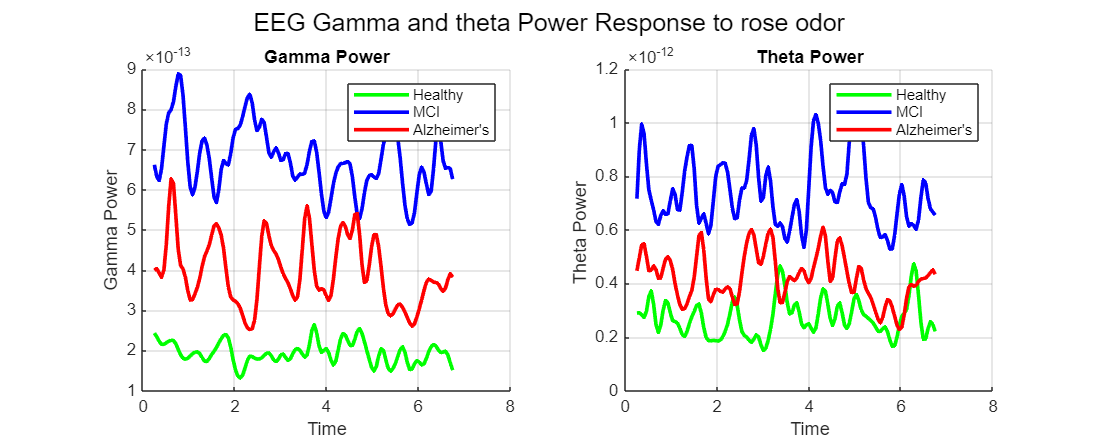

figure('Position', [5, 5, 3000, 1200]);

% Subplot 1: Chocolate Odor
subplot(1, 2, 1);
hold on;
plot(T, h_rose_gam, 'g', 'LineWidth', 2, 'DisplayName', 'Healthy');
plot(T, ci_rose_gam, 'b', 'LineWidth', 2, 'DisplayName', 'MCI');
plot(T, ad_rose_gam, 'r', 'LineWidth', 2, 'DisplayName', 'Alzheimer''s');
title('Gamma Power');
xlabel('Time');
ylabel('Gamma Power');
legend('show');
grid on;
hold off;

% Subplot 2: Rose Odor
subplot(1, 2, 2);
hold on;
plot(T, h_rose_thet, 'g', 'LineWidth', 2, 'DisplayName', 'Healthy');
plot(T, ci_rose_thet, 'b', 'LineWidth', 2, 'DisplayName', 'MCI');
plot(T, ad_rose_thet, 'r', 'LineWidth', 2, 'DisplayName', 'Alzheimer''s');
title('Theta Power');
xlabel('Time');
ylabel('Theta Power ');
legend('show');
grid on;
hold off;


sgtitle('EEG Gamma and theta Power Response to rose odor'); % Super title

## Power-Time Plot Insights: 

### 1.Timing and Strength of Peak Power 

When stimulated by their senses, healthy people usually show strong and punctual peaks in the gamma (30–50 Hz) and theta (4–8 Hz) frequency bands.

Patients with AD and MCI exhibit delayed and diminished peaks, especially in the gamma band. Research shows that AD patients' gamma oscillations, which are linked to cognitive processes like memory and attention, are much lower than those of healthy controls.

### 2.Differences in the Odor of Chocolate and Rose 

Patients with AD and MCI are known to have impaired olfactory processing in general. Regardless of the particular odor, this impairment may result in reduced EEG responses to olfactory stimuli.

### 3. **Consistent Delays or Drops in MCI and AD Responses**

Theta Band: Patients with AD may exhibit increased theta power, which could be a result of compensatory mechanisms or a pathological slowing of brain activity.Gamma Band: Both AD and MCI patients exhibit a significant drop in gamma power, which suggests impaired cognitive processing and disturbed neural synchrony.These changes point to a regular pattern of delayed and reduced EEG responses in MCI and AD patients when compared to healthy people.

### 4. **Impact on Theta and Gamma Bands in Impaired States**

Theta Band: Alterations in theta activity are prominent in MCI and AD, with increased power potentially serving as a biomarker for early cognitive decline . 

Gamma Band: Reductions in gamma power are more pronounced in AD patients, correlating with the severity of cognitive impairment . Overall, both theta and gamma bands are affected in impaired states, but gamma band disruptions are more closely associated with advanced stages of cognitive decline.